# SBT_CW.mat Data Cleaning

Simple Box Test, Clock Wise

David Olson

04 Sep 2021

% Start Fresh
close all
clear all
clc

% Define Constants
Fs = 50; % Hz - confirmed via hand-written notes
dt = 1 / Fs;
init_time = 12; % Time spent sitting still before test for initialization

% Load Raw Data
load("SBT_CW_raw.mat")

## Accelerometer Data Cleaning

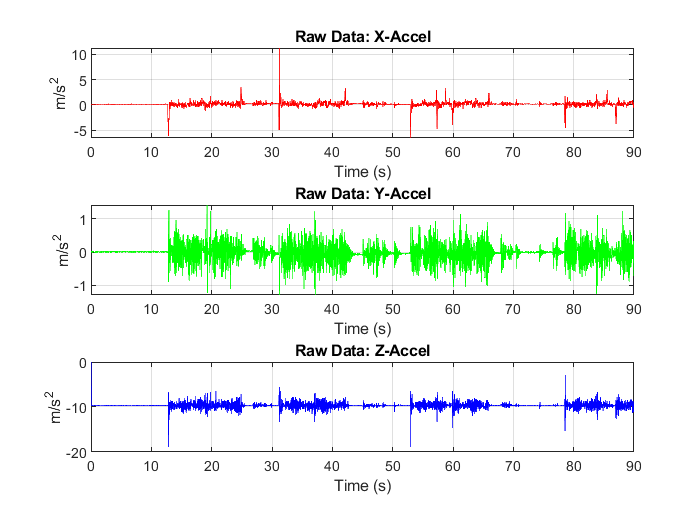

% Plot Data to see how it looks
figure(1)
subplot(3,1,1)
plot(t, accel(:,1), 'r')
title('Raw Data: X-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,2)
plot(t, accel(:,2), 'g')
title('Raw Data: Y-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,3)
plot(t, accel(:,3), 'b')
title('Raw Data: Z-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on

**Data looks good, no need for adjustment**

## Gyroscope Data Cleaning

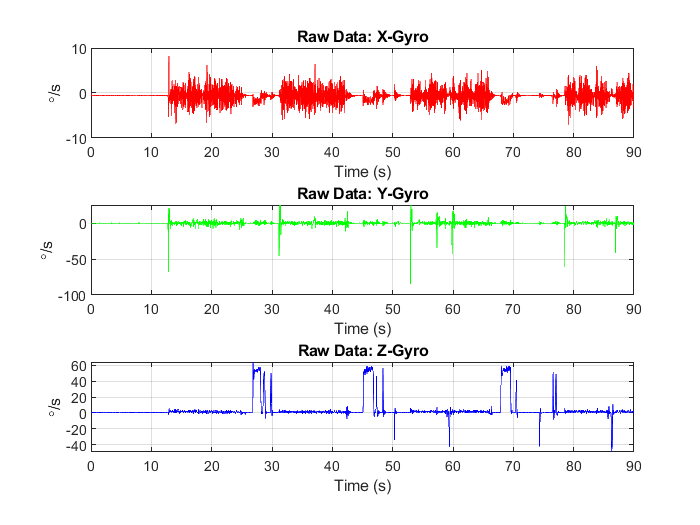

% Plot Data to see how it looks
figure(2)
subplot(3,1,1)
plot(t, gyro(:,1) * 180/pi, 'r')
title('Raw Data: X-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,2)
plot(t, gyro(:,2) * 180/pi, 'g')
title('Raw Data: Y-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,3)
plot(t, gyro(:,3) * 180/pi, 'b')
title('Raw Data: Z-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on

**Data looks good, no need for adjustment**

Y-gyro spikes hard as expected with tilt from the robot

## Odometry Data Cleaning

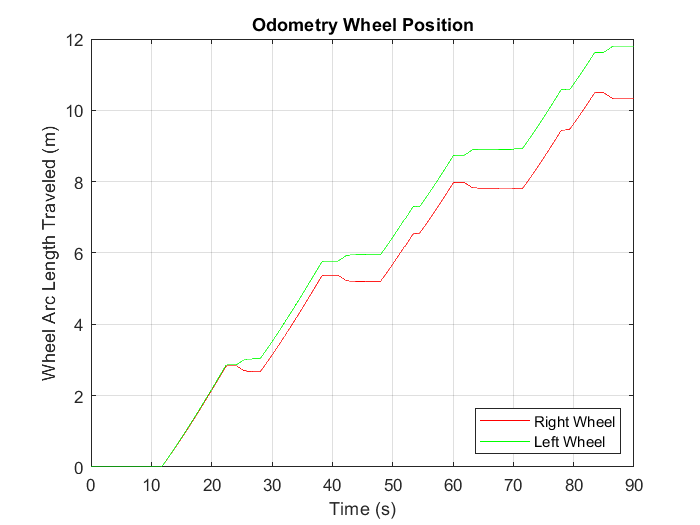

figure(3)
plot(t, odo(:,1), 'r', t, odo(:,2), 'g')
title('Odometry Wheel Position')
xlabel('Time (s)')
ylabel('Wheel Arc Length Traveled (m)')
legend('Right Wheel', 'Left Wheel', 'Location', "SouthEast")
grid on

**Data looks good, no need for adjustment**

## **Depth Camera Data Cleaning**

   
% Pre-Allocate
[kinect_samples, ~] = size(depth);
numPoints = 5000;
xyz = zeros(3, numPoints, kinect_samples);

% Convert to XYZ with down-sampling
tic
for k = 2 : kinect_samples
    xyz(:,:,k) = depth2xyz(depth, numPoints, k);
end
toc

Elapsed time is 7.742007 seconds.


## Depth Camera Animation

% % Show Animation
% for k = 2 : kinect_samples
%     
%     figure
%     hold on
%     plot3(xyz(1,:,k), xyz(2,:,k), xyz(3,:,k), 'b.');
%     viscircles([0,0], 0.35, 'Color', 'k');
%     quiver3(0,0,0,0.5,0,0, 'Color', 'r', 'LineWidth', 3);
%     title(['Kinect Point Cloud:   t = ', num2str(k)])
%     xlabel('X (m)')
%     ylabel('Y (m)')
%     zlabel('Z (m)')
%     xlim([-0.5 3.5])
%     
%     axis equal
%     view([-156.521 13.341])
%     grid on
%     hold off
%     
% %     pause(1)
%     
% %     dummy = input('Hit Enter to Move to Next Frame, Hit Q to Quit:  ', "s");
% %     if (dummy == 'Q')
% %         break
% %     end
% %     clf(4)
% %     clc
%     
% end

% Establish Point Cloud Processing Parameters
[~, K, num_frames] = size(xyz);

% Convert 3D Matrix into Cell Array
new_xyz = cell(num_frames,1);
for n = 1 : num_frames
    new_xyz{n} = xyz(:,:,n);
end
xyz = new_xyz;

## Separate Point Cloud Data into Wall and Floor Points

% Define Thresholds
x_thres = 1.5;
z_thres = 0;

% Separate Points
xyz_wall = cell(num_frames,1);
xyz_floor = cell(num_frames,1);

for n = 2 : num_frames
    
    % Remove all {0;0;0] measurements
    zero_mask = logical(sum(xyz{n}) ~= 0);
    xyz{n} = xyz{n}(:,zero_mask);
    
    % Locate and Store floor points
    floor_mask = (xyz{n}(1,:) < x_thres) & (xyz{n}(3,:) < z_thres);
    xyz_floor{n} = xyz{n}(:,floor_mask);
    
    % Locate and Store wall points
    wall_mask = (xyz{n}(3,:) >= z_thres);
    xyz_wall{n} = xyz{n}(:,wall_mask);
    
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Thresholding
test_point_cloud_flag = false;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz{test_frame}, ['Full Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
end

## Verify the attitude of the floor with a quick test case

% % Verify Good Floor Data
% test_frame = 22;
% plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
% % Pitch of two Example Points
% atan2(-0.03661 - -0.03142, 1.316 - 0.4602) * 180/pi
% % Accomplish Crude Prediction of "Ground Truth" Pitch Values
% pitch = zeros(1, num_frames);
% for n = 2 : num_frames
%     
%     % Grab and Average All Points between x = 0.5 & x = 0.6
%     xyz_floor_back_mask = (xyz_floor{n}(1,:) > 0.5) & (xyz_floor{n}(1,:) < 0.6);
%     xyz_back_avg = mean(xyz_floor{n}(:,xyz_floor_back_mask)')';
%     
%     % Grab and Average All Points between x = 0.9 & x = 0.1
%     xyz_floor_front_mask = (xyz_floor{n}(1,:) > 0.9) & (xyz_floor{n}(1,:) < 1);
%     xyz_front_avg = mean(xyz_floor{n}(:,xyz_floor_front_mask)')';
%     
%     pitch(n) = atan2(xyz_front_avg(3) - xyz_back_avg(3), xyz_front_avg(1) - xyz_back_avg(1));
%     
% end
% 
% % Plot "Ground Truth" Estimate of Pitch
% plot(2:num_frames, pitch(2:end) * 180/pi, 'g*')
% title('"Ground Truth" Pitch Guesses')
% xlabel('Frames')
% xlim([2 num_frames])
% ylabel('Pitch (\circ)')
% grid on

## Shift Wall and Floor Point Clouds to the Origin

% Locate and Shift each floor point cloud to the origin
% for n = 2 : num_frames
% %     x_max = max(xyz_floor{n}(1,:));
% %     x_min = min(xyz_floor{n}(1,:));
% %     x_shift = x_min + ((x_max - x_min)/2);
% %     y_max = max(xyz_floor{n}(2,:));
% %     y_min = min(xyz_floor{n}(2,:));
% %     y_shift = y_min + ((y_max - y_min)/2);
%     xyz_floor{n} = xyz_floor{n} - [0.5; 0; 0];
% end
% 
% Locate and Shift each wall point cloud to the origin
for n = 2 : num_frames
    x_max = max(xyz_wall{n}(1,:));
    x_min = min(xyz_wall{n}(1,:));
    x_shift = x_min + ((x_max - x_min)/2);
    xyz_wall{n} = xyz_wall{n} - [x_shift; 0; 0];
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Point Cloud Shifting
test_point_cloud_flag = false;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    hold on
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
%     quiver3(0,0,0,cos(3*pi/180),0,sin(3*pi/180))
    hold off
end

## Complete the SNHT Floor Search

Searching for pitch only!

Begin Processing Frame #2

Elapsed time is 1.398127 seconds.


Begin Processing Frame #3

Elapsed time is 1.393315 seconds.


Begin Processing Frame #4

Elapsed time is 1.395954 seconds.


Begin Processing Frame #5

Elapsed time is 1.373652 seconds.


Begin Processing Frame #6

Elapsed time is 1.365325 seconds.


Begin Processing Frame #7

Elapsed time is 1.434527 seconds.


Begin Processing Frame #8

Elapsed time is 1.415573 seconds.


Begin Processing Frame #9

Elapsed time is 1.408192 seconds.


Begin Processing Frame #10

Elapsed time is 1.404535 seconds.


Begin Processing Frame #11

Elapsed time is 1.402062 seconds.


Begin Processing Frame #12

Elapsed time is 1.359781 seconds.


Begin Processing Frame #13

Elapsed time is 1.405824 seconds.


Begin Processing Frame #14

Elapsed time is 1.351932 seconds.


Begin Processing Frame #15

Elapsed time is 1.351165 seconds.


Begin Processing Frame #16

Elapsed time is 1.354742 seconds.


Begin Processing Frame #17

Elapsed time is 1.076925 seconds.


Begin Processing Frame #18

Elapsed time is 1.055752 seconds.


Begin Processing Frame #19

Elapsed time is 1.051531 seconds.


Begin Processing Frame #20

Elapsed time is 1.025654 seconds.


Begin Processing Frame #21

Elapsed time is 1.053533 seconds.


Begin Processing Frame #22

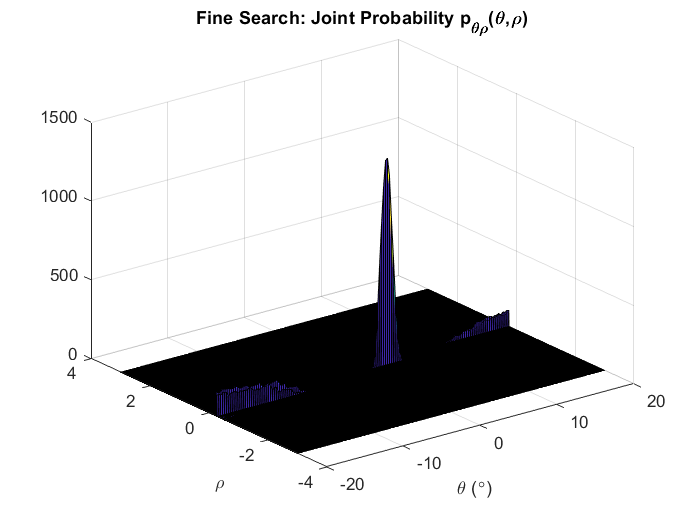

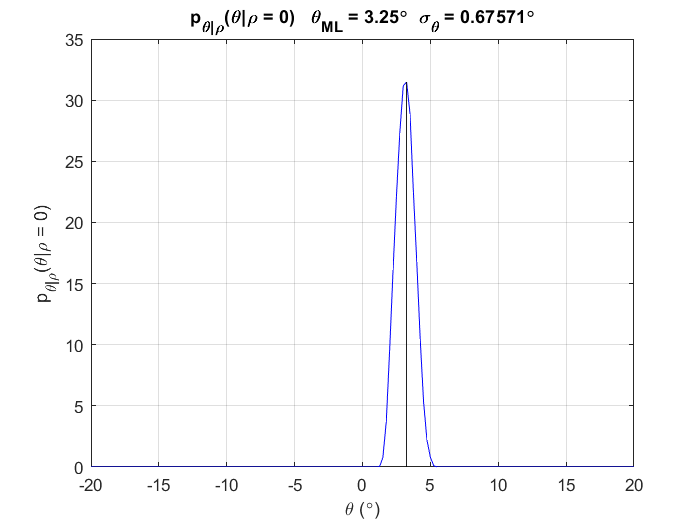

Elapsed time is 1.168019 seconds.


Begin Processing Frame #23

Elapsed time is 0.971644 seconds.


Begin Processing Frame #24

Elapsed time is 0.843641 seconds.


Begin Processing Frame #25

Elapsed time is 0.755135 seconds.


Begin Processing Frame #26

Elapsed time is 0.662575 seconds.


Begin Processing Frame #27

Elapsed time is 1.011532 seconds.


Begin Processing Frame #28

Elapsed time is 1.278345 seconds.


Begin Processing Frame #29

Elapsed time is 1.351916 seconds.


Begin Processing Frame #30

Elapsed time is 1.355377 seconds.


Begin Processing Frame #31

Elapsed time is 1.295282 seconds.


Begin Processing Frame #32

Elapsed time is 1.267232 seconds.


Begin Processing Frame #33

Elapsed time is 1.020034 seconds.


Begin Processing Frame #34

Elapsed time is 1.034318 seconds.


Begin Processing Frame #35

Elapsed time is 0.999959 seconds.


Begin Processing Frame #36

Elapsed time is 1.015428 seconds.


Begin Processing Frame #37

Elapsed time is 0.987435 seconds.


Begin Processing Frame #38

Elapsed time is 1.005289 seconds.


Begin Processing Frame #39

Elapsed time is 0.999347 seconds.


Begin Processing Frame #40

Elapsed time is 0.902611 seconds.


Begin Processing Frame #41

Elapsed time is 0.829577 seconds.


Begin Processing Frame #42

Elapsed time is 0.793972 seconds.


Begin Processing Frame #43

Elapsed time is 0.875332 seconds.


Begin Processing Frame #44

Elapsed time is 1.076805 seconds.


Begin Processing Frame #45

Elapsed time is 1.383107 seconds.


Begin Processing Frame #46

Elapsed time is 1.336935 seconds.


Begin Processing Frame #47

Elapsed time is 1.338123 seconds.


Begin Processing Frame #48

Elapsed time is 1.284600 seconds.


Begin Processing Frame #49

Elapsed time is 1.364461 seconds.


Begin Processing Frame #50

Elapsed time is 0.312360 seconds.


Begin Processing Frame #51

Elapsed time is 1.393006 seconds.


Begin Processing Frame #52

Elapsed time is 1.364936 seconds.


Begin Processing Frame #53

Elapsed time is 1.099897 seconds.


Begin Processing Frame #54

Elapsed time is 1.119793 seconds.


Begin Processing Frame #55

Elapsed time is 1.097830 seconds.


Begin Processing Frame #56

Elapsed time is 1.126017 seconds.


Begin Processing Frame #57

Elapsed time is 1.093138 seconds.


Begin Processing Frame #58

Elapsed time is 1.030820 seconds.


Begin Processing Frame #59

Elapsed time is 0.958346 seconds.


Begin Processing Frame #60

Elapsed time is 0.904771 seconds.


Begin Processing Frame #61

Elapsed time is 0.953402 seconds.


Begin Processing Frame #62

Elapsed time is 0.805906 seconds.


Begin Processing Frame #63

Elapsed time is 0.693515 seconds.


Begin Processing Frame #64

Elapsed time is 0.802359 seconds.


Begin Processing Frame #65

Elapsed time is 1.158761 seconds.


Begin Processing Frame #66

Elapsed time is 1.299621 seconds.


Begin Processing Frame #67

Elapsed time is 1.287788 seconds.


Begin Processing Frame #68

Elapsed time is 1.284819 seconds.


Begin Processing Frame #69

Elapsed time is 1.352137 seconds.


Begin Processing Frame #70

Elapsed time is 1.300051 seconds.


Begin Processing Frame #71

Elapsed time is 1.229007 seconds.


Begin Processing Frame #72

Elapsed time is 1.294114 seconds.


Begin Processing Frame #73

Elapsed time is 1.370786 seconds.


Begin Processing Frame #74

Elapsed time is 1.379709 seconds.


Begin Processing Frame #75

Elapsed time is 1.441569 seconds.


Begin Processing Frame #76

Elapsed time is 1.129404 seconds.


Begin Processing Frame #77

Elapsed time is 1.034363 seconds.


Begin Processing Frame #78

Elapsed time is 1.007897 seconds.


Begin Processing Frame #79

Elapsed time is 1.026180 seconds.


Begin Processing Frame #80

Elapsed time is 0.961576 seconds.


Begin Processing Frame #81

Elapsed time is 0.998078 seconds.


Begin Processing Frame #82

Elapsed time is 0.951638 seconds.


Begin Processing Frame #83

Elapsed time is 0.928588 seconds.


Begin Processing Frame #84

Elapsed time is 0.987960 seconds.


Begin Processing Frame #85

Elapsed time is 0.863244 seconds.


Begin Processing Frame #86

Elapsed time is 0.729376 seconds.


Begin Processing Frame #87

Elapsed time is 0.847667 seconds.


Begin Processing Frame #88

Elapsed time is 1.039401 seconds.


Begin Processing Frame #89

Elapsed time is 1.349175 seconds.


Begin Processing Frame #90

Elapsed time is 1.329827 seconds.


Begin Processing Frame #91

Elapsed time is 1.314688 seconds.


% Pre-Allocate Memory
theta_meas = zeros(1,91);
theta_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [theta_meas(n), theta_sigmas(n)] = SNHT_pitch(xyz_floor{n}, plot_flag);
    toc
    
end

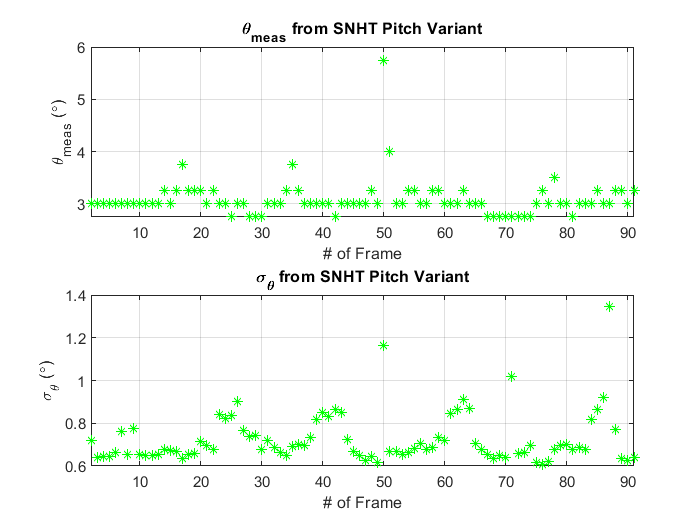

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, theta_meas * 180/pi, 'g*')
title('\theta_m_e_a_s from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\theta_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, theta_sigmas * 180/pi, 'g*')
title('\sigma_\theta from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\theta (\circ)')
grid on

## Process Wall Point Clouds

Begin Processing Frame #2

Elapsed time is 0.857229 seconds.


Begin Processing Frame #3

Elapsed time is 0.839801 seconds.


Begin Processing Frame #4

Elapsed time is 0.763649 seconds.


Begin Processing Frame #5

Elapsed time is 0.809547 seconds.


Begin Processing Frame #6

Elapsed time is 0.845794 seconds.


Begin Processing Frame #7

Elapsed time is 0.825993 seconds.


Begin Processing Frame #8

Elapsed time is 0.929809 seconds.


Begin Processing Frame #9

Elapsed time is 0.812780 seconds.


Begin Processing Frame #10

Elapsed time is 0.820199 seconds.


Begin Processing Frame #11

Elapsed time is 0.826308 seconds.


Begin Processing Frame #12

Elapsed time is 0.868747 seconds.


Begin Processing Frame #13

Elapsed time is 0.781012 seconds.


Begin Processing Frame #14

Elapsed time is 0.713941 seconds.


Begin Processing Frame #15

Elapsed time is 0.789262 seconds.


Begin Processing Frame #16

Elapsed time is 0.731909 seconds.


Begin Processing Frame #17

Elapsed time is 1.737631 seconds.


Begin Processing Frame #18

Elapsed time is 1.990136 seconds.


Begin Processing Frame #19

Elapsed time is 2.064695 seconds.


Begin Processing Frame #20

Elapsed time is 2.622051 seconds.


Begin Processing Frame #21

Elapsed time is 2.535248 seconds.


Begin Processing Frame #22

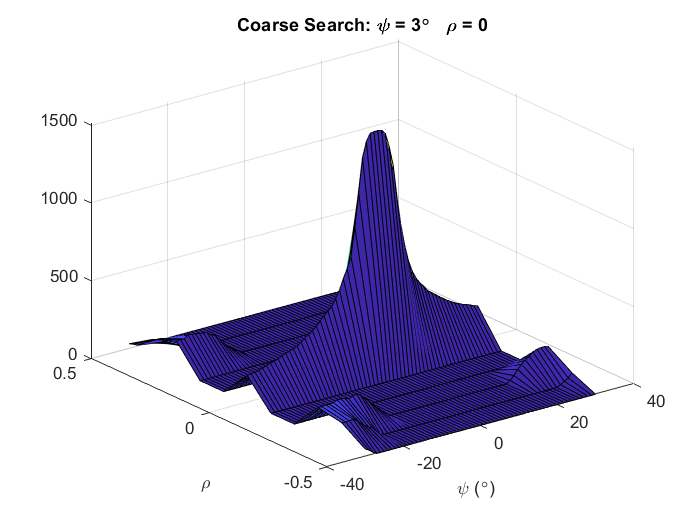

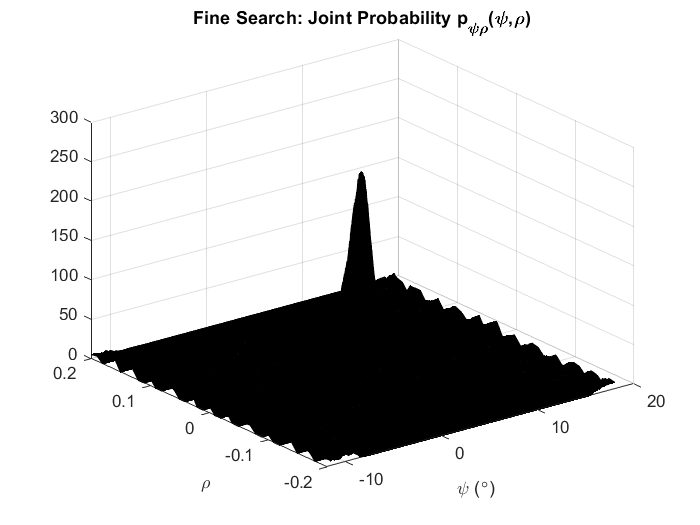

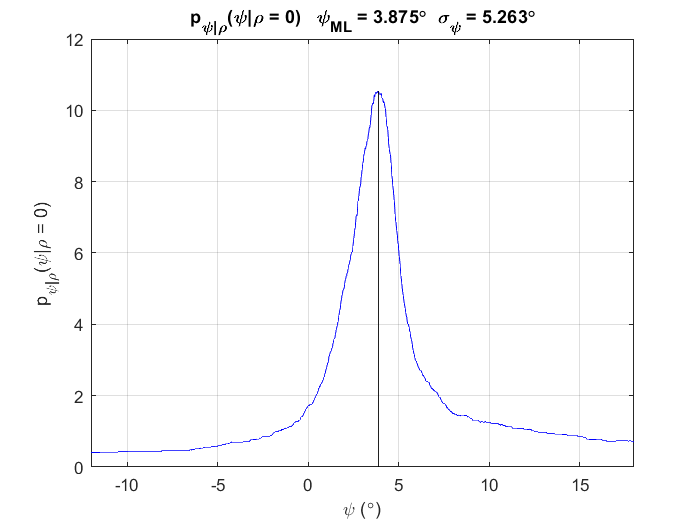

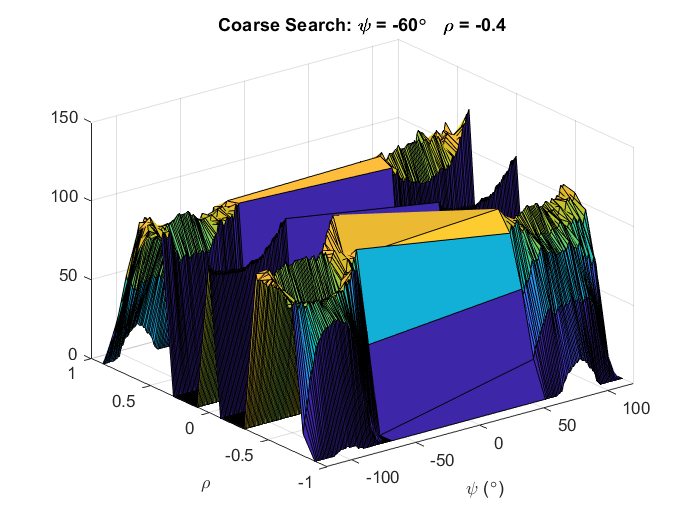

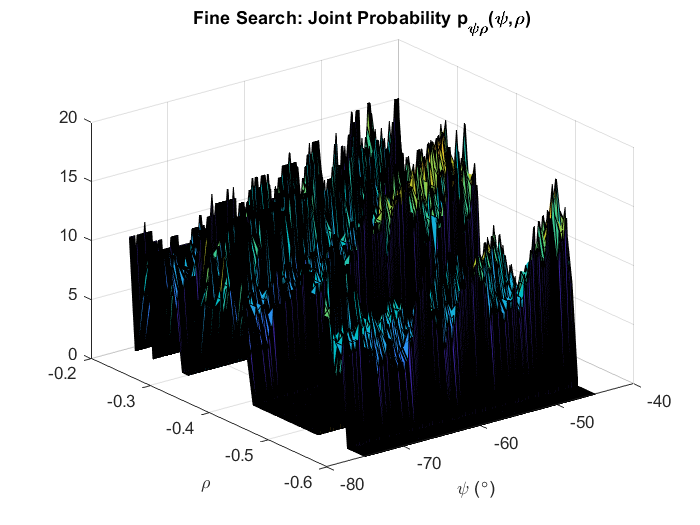

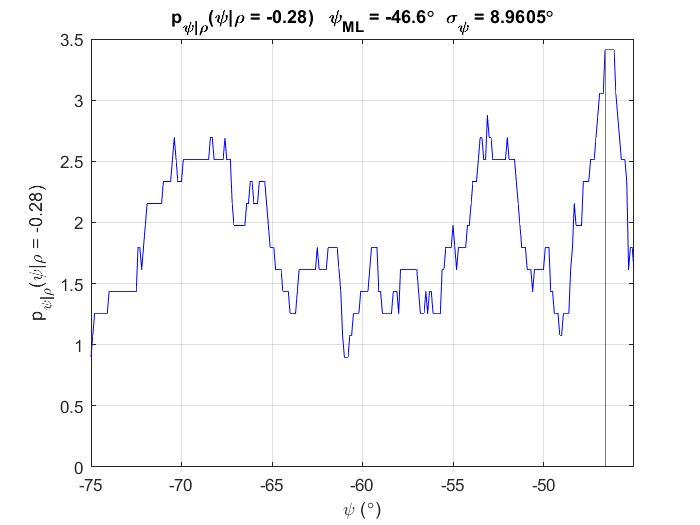

Elapsed time is 3.399523 seconds.


Begin Processing Frame #23

Elapsed time is 3.302127 seconds.


Begin Processing Frame #24

Elapsed time is 4.042406 seconds.


Begin Processing Frame #25

Elapsed time is 4.875685 seconds.


Begin Processing Frame #26

Elapsed time is 5.520571 seconds.


Begin Processing Frame #27

Elapsed time is 3.254137 seconds.


Begin Processing Frame #28

Elapsed time is 1.059454 seconds.


Begin Processing Frame #29

Elapsed time is 0.750260 seconds.


Begin Processing Frame #30

Elapsed time is 0.747073 seconds.


Begin Processing Frame #31

Elapsed time is 0.661191 seconds.


Begin Processing Frame #32

Elapsed time is 0.693330 seconds.


Begin Processing Frame #33

Elapsed time is 1.871760 seconds.


Begin Processing Frame #34

Elapsed time is 1.838616 seconds.


Begin Processing Frame #35

Elapsed time is 1.883094 seconds.


Begin Processing Frame #36

Elapsed time is 2.300595 seconds.


Begin Processing Frame #37

Elapsed time is 2.357715 seconds.


Begin Processing Frame #38

Elapsed time is 2.695209 seconds.


Begin Processing Frame #39

Elapsed time is 3.165072 seconds.


Begin Processing Frame #40

Elapsed time is 3.807573 seconds.


Begin Processing Frame #41

Elapsed time is 4.303129 seconds.


Begin Processing Frame #42

Elapsed time is 4.349372 seconds.


Begin Processing Frame #43

Elapsed time is 3.962172 seconds.


Begin Processing Frame #44

Elapsed time is 2.301556 seconds.


Begin Processing Frame #45

Elapsed time is 0.615731 seconds.


Begin Processing Frame #46

Elapsed time is 0.339210 seconds.


Begin Processing Frame #47

Elapsed time is 0.393780 seconds.


Begin Processing Frame #48

Elapsed time is 0.574155 seconds.


Begin Processing Frame #49

Elapsed time is 0.583855 seconds.


Begin Processing Frame #50

Elapsed time is 4.749912 seconds.


Begin Processing Frame #51

Elapsed time is 0.455555 seconds.


Begin Processing Frame #52

Elapsed time is 0.335920 seconds.


Begin Processing Frame #53

Elapsed time is 1.678002 seconds.


Begin Processing Frame #54

Elapsed time is 2.120428 seconds.


Begin Processing Frame #55

Elapsed time is 2.212595 seconds.


Begin Processing Frame #56

Elapsed time is 2.164621 seconds.


Begin Processing Frame #57

Elapsed time is 2.579241 seconds.


Begin Processing Frame #58

Elapsed time is 2.557226 seconds.


Begin Processing Frame #59

Elapsed time is 2.643846 seconds.


Begin Processing Frame #60

Elapsed time is 3.021647 seconds.


Begin Processing Frame #61

Elapsed time is 3.656970 seconds.


Begin Processing Frame #62

Elapsed time is 4.306826 seconds.


Begin Processing Frame #63

Elapsed time is 5.004287 seconds.


Begin Processing Frame #64

Elapsed time is 4.329568 seconds.


Begin Processing Frame #65

Elapsed time is 2.361345 seconds.


Begin Processing Frame #66

Elapsed time is 1.248267 seconds.


Begin Processing Frame #67

Elapsed time is 0.892395 seconds.


Begin Processing Frame #68

Elapsed time is 0.933727 seconds.


Begin Processing Frame #69

Elapsed time is 0.926772 seconds.


Begin Processing Frame #70

Elapsed time is 1.171582 seconds.


Begin Processing Frame #71

Elapsed time is 1.253860 seconds.


Begin Processing Frame #72

Elapsed time is 0.916712 seconds.


Begin Processing Frame #73

Elapsed time is 0.507995 seconds.


Begin Processing Frame #74

Elapsed time is 0.358704 seconds.


Begin Processing Frame #75

Elapsed time is 0.322435 seconds.


Begin Processing Frame #76

Elapsed time is 1.820593 seconds.


Begin Processing Frame #77

Elapsed time is 2.092804 seconds.


Begin Processing Frame #78

Elapsed time is 2.116491 seconds.


Begin Processing Frame #79

Elapsed time is 2.543103 seconds.


Begin Processing Frame #80

Elapsed time is 2.826732 seconds.


Begin Processing Frame #81

Elapsed time is 2.612663 seconds.


Begin Processing Frame #82

Elapsed time is 2.538388 seconds.


Begin Processing Frame #83

Elapsed time is 2.853893 seconds.


Begin Processing Frame #84

Elapsed time is 3.436211 seconds.


Begin Processing Frame #85

Elapsed time is 3.903930 seconds.


Begin Processing Frame #86

Elapsed time is 4.825158 seconds.


Begin Processing Frame #87

Elapsed time is 4.296539 seconds.


Begin Processing Frame #88

Elapsed time is 2.691224 seconds.


Begin Processing Frame #89

Elapsed time is 0.576463 seconds.


Begin Processing Frame #90

Elapsed time is 0.604623 seconds.


Begin Processing Frame #91

Elapsed time is 0.596905 seconds.


% Pre-Allocate Memory
psi_fw_meas = zeros(1,91);
psi_fw_sigmas = zeros(1,91);
psi_sw_meas = zeros(1,91);
psi_sw_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [psi_fw_meas(n), psi_fw_sigmas(n)] = SNHT_front_wall(xyz_wall{n}, plot_flag);
    [psi_sw_meas(n), psi_sw_sigmas(n)] = SNHT_side_wall(xyz_wall{n}, plot_flag);
    toc
    
end

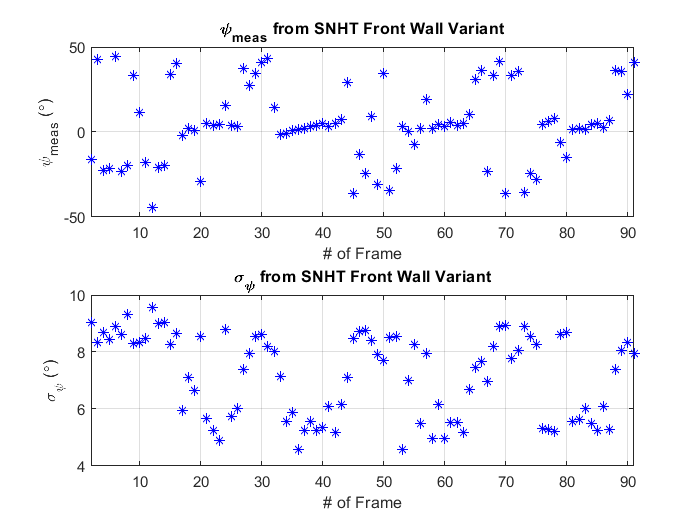

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, psi_fw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_fw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

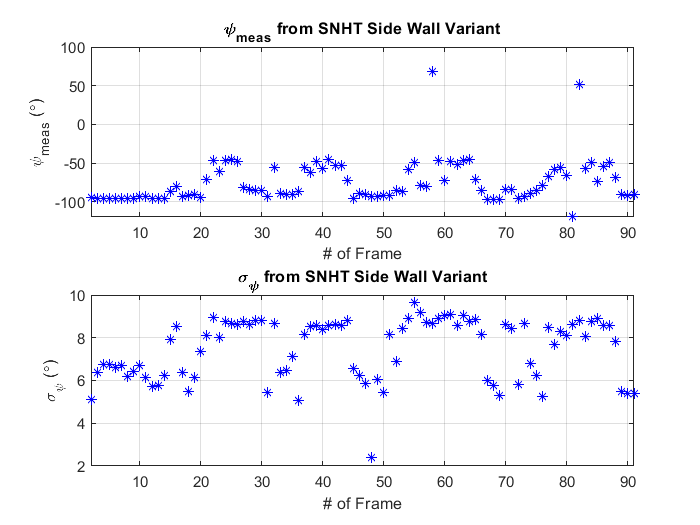

figure
subplot(2,1,1)
plot(1:num_frames, psi_sw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_sw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

## Save Data

% Transpose Everything to the Same Format
t = t';
accel = accel';
gyro = gyro';
odo = odo';

% Save to Structure
P.Fs = Fs;                         % Hz
P.dt = dt;                         % s
P.t = t;                           % s
P.t_end = t(end);                  % s
P.init_time = init_time;           % s
P.accel = double(accel);           % m/s^2
P.gyro = double(gyro);             % rad/s
P.odo = odo;                       % m
P.baro = 84.5*ones(1, length(t));  % kPa -- fake measurement for now!
P.theta_meas = theta_meas;         % rad
P.theta_sigmas = theta_sigmas;     % rad
P.psi_fw_meas = psi_fw_meas;       % rad
P.psi_fw_sigmas = psi_fw_sigmas;   % rad
P.psi_sw_meas = psi_sw_meas;       % rad
P.psi_sw_sigmas = psi_sw_sigmas;   % rad

save("SBT_CW.mat", 'P')

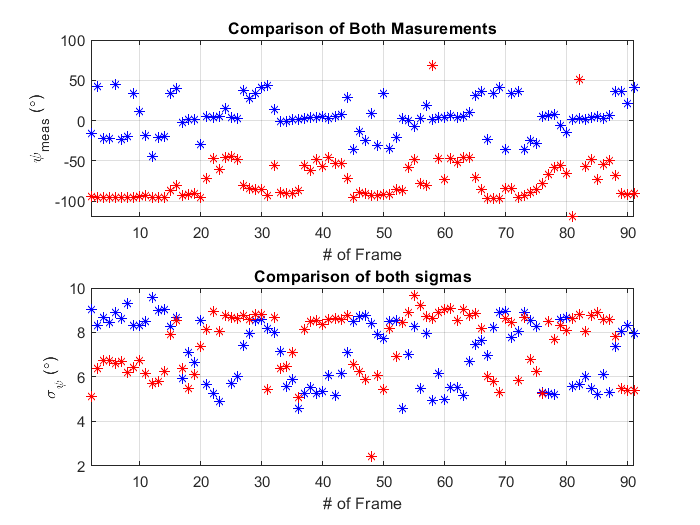

% Quick Test
figure
subplot(2,1,1)
plot(1:num_frames, psi_fw_meas * 180/pi, 'b*', 1:num_frames, psi_sw_meas * 180/pi, 'r*')
title('Comparison of Both Masurements')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_fw_sigmas * 180/pi, 'b*', 1:num_frames, psi_sw_sigmas * 180/pi, 'r*')
title('Comparison of both sigmas')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on